%Initializing the values for computation
R = 0.05;
H = 4.0;
K = 0.95;
Fh = 0.3;
Tr = 8.0;
D = 1.0;

Ps = 0.3; %Initializing the P-step value


%Initializing t and s
t = sym('t')

$$t = t$$

s = sym('s')

$$s = s$$

syms tau positive
syms tau2 positive

%Calculating  𝜔𝑛 
wn2 = (D*R+K)/(2*H*R*Tr)

wn2 = 0.3125

wn = sqrt(wn2)

wn = 0.5590


%Calculating  𝜁 
c = (((2*H*R)+(((D*R)+(K*Fh))*Tr))/(2*(D*R+K)))*wn 

c = 0.8609

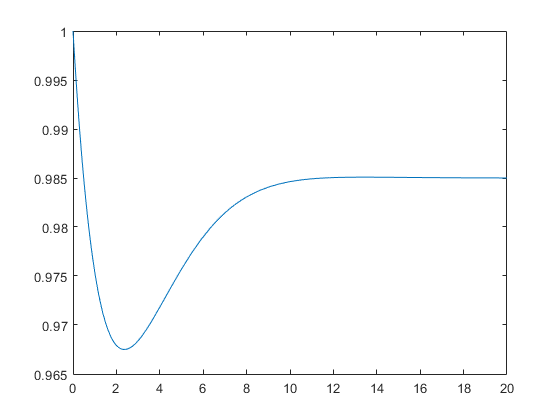



%Calculating alpha
a = sqrt((1-2*Tr*c*wn+(Tr^2)*(wn^2))/(1-(c^2)));

%Calculating 𝜔r
wr = wn*(sqrt(1-(c^2)));

%Calculating the angle (In Radians)
phi = atan((wr*Tr)/(1-c*wn*Tr))-atan(sqrt(1-(c^2))/(-c));


ft = vpa(1 - ((R*Ps)/(D*R+K))*(1+a*exp(-c*wn*t)*sin(wr*t+phi)));
fplot(ft)
xlim([0 20])
ylim([0.965 1])


%Defining the frequency Nadir
fs = 1 - ((R*Ps)/(D*R+K));
tn = (1/wr)*atan((wr*Tr)/(c*wn*Tr-1));
fn = 1 - ((R*Ps)/(D*R+K))*(1+a*exp(-c*wn*tn)*sin(wr*tn+phi));


%Declare the correction Factor
B = 0.8;
Dtr = fs - fn;
%The new frequency Nadir with the correction Factor
fnew = B*Dtr + fn;


%Declare and compute Tau and Tau2
sympref('HeavisideAtOrigin',1);
tau = vpasolve(ft-(B*Dtr+fn)==0,t)

$$tau = 0.64850059178443801858717064354481$$

tau2 = vpasolve(ft-(B*Dtr+fn)==0,t,2*tn)

$$tau2 = 7.0294249087066162204973329548659$$

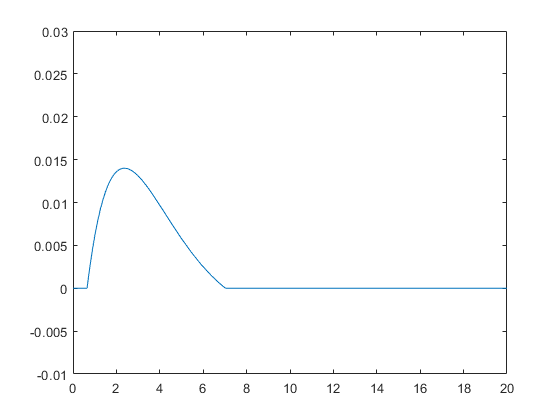



%Define the function Delta Frequency, and plot in the time domain
dft = (fnew - ft)*(heaviside(t-tau) - heaviside(t-tau2));
fplot(dft)
xlim([0 20])
ylim([-0.01 0.03])



%final equation to get power injection
dFs = laplace(dft,t,s)

$$dFs = \begin{array}{l} -\frac{1.0e-35\,\left(2.6878933465079738655164786536269e+33\,\sigma_{3}-87476464401284648175760594313033.0\,{\mathrm{e}}^{0.48125\,t}\right)\,\left(7.5444878895961299585053265872158e+66\,\sigma_{2}-2.0749001824649199597212927280848e+66\,\sigma_{1}-2.9152681744599625270211008511072e+67\,\sigma_{1}\,\left(s+0.48125\right)+2.5894004557883853235188848589352e+33\,\sigma_{2}\,{\left(s+0.48125\right)}^{2}+1.074128997079165500060460036548e+36\,\sigma_{1}\,{\left(s+0.48125\right)}^{2}-1.4124685911288514716391857272475e+67\,\sigma_{2}\,\left(s+0.48125\right)\right)}{s\,\left(5.0e+33\,{\left(s+0.48125\right)}^{2}+404492187500000000000000000000000.0\right)\,\left(2.6878933465079738655164786536269e+33\,\sigma_{3}-87476464401284648175760594313033.0\,{\mathrm{e}}^{0.48125\,t}\right)}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-7.0294249087066162204973329548659\,s-3.3829107373150590561143414845292}\\ \sigma_{2}={\mathrm{e}}^{-0.64850059178443801858717064354481\,s-0.31209090979626079644507587220594}\\ \sigma_{3}=\sin\left(0.28442650632456884291693803355929\,t-0.13997106650463042587517747961101\right) \end{array}$$

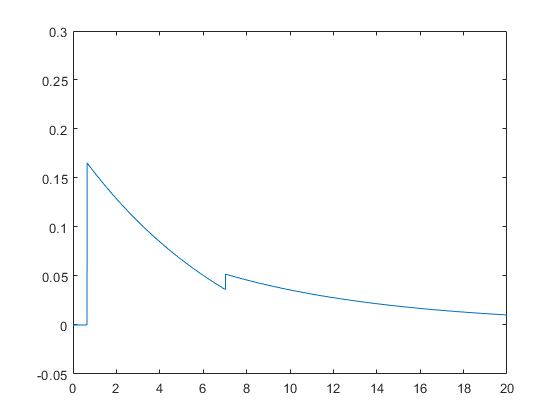



GSFR = ((R*(wn^2))/(D*R+K))*((1+Tr*s)/((s^2)+2*c*wn*s+(wn^2)));

dPs = dFs/GSFR;

dpt = ilaplace(dPs,s,t);
 
 
fplot(dpt, [0 20])
xlim([0 20])
ylim([-0.05 0.3])